# Generate (qu,pu) Coordinates

This script provides the $(q_u,p_u)$ equations of motion for the simple acrobot, given the VNCH $q_a = \bar{q_a}\tan^{-1}(I p_u)$. These equations of motion were simplified by hand from the original expression generated by MATLAB.

close all
clc;

% Set the physical dynamics of the acrobot
mass = 1; % kg
len = 1; % m
grav = 1; % m/s^2
scale = min(1,sqrt(3/(10*mass^2*grav*len^3)));

% Set the ode solver options
baseOptions = odeset('RelTol',10^-13,'AbsTol',10^-13);
q0 = 1; % Initial angle (rad)
T0 = 0; T1 = 100; % Time frame of solution [T0, T1]

% Set the symbolic variables for dynamics
m = sym('m','positive'); % mass of each link
g = sym('g','positive'); % gravitational acceleration
l = sym('l','positive'); % length of the acrobot's links
I = sym('I','positive'); % scaling of the actuator
qu = sym('qu');
pu = sym('pu');
% Set the actuator symbolically
qa = atan(I*pu);
% Get the derivative of h(q) = qa - atan(I*pu) = 0 wrt pu
dhp = -simplify(diff(qa,pu));

% Define shorthand variable
su = sin(qu);
sa = sin(qa);
cu = cos(qu);
ca = cos(qa);
R = (su*(2+ca) + cu*sa); %(2su + sua) expanded out

% Write out the expressions for the (qu,pu) eom
qud = (pu - m^2*g*l^3*R*(1+ca)*dhp)/(m*l^2*(3+2*ca));
pud = -m*g*l*R;

% Get the ode for (qu,pu)'s eom
f = matlabFunction(...
    subs([qud;pud], [m g l I], [mass len grav scale]),...
    'vars',[qu,pu]);
% Display the path of the ode
sol = ode45(                      ...
    @(t,x)f(wrapToPi(x(1)),x(2)), ... % ode
    [T0, T1],                     ... % time interval
    [q0;0],                       ... % initial conditions
    baseOptions);                     % solver options

% Convert the output to the cylinder by wrapping q-values
sol.y(1,:) = wrapToPi(sol.y(1,:));

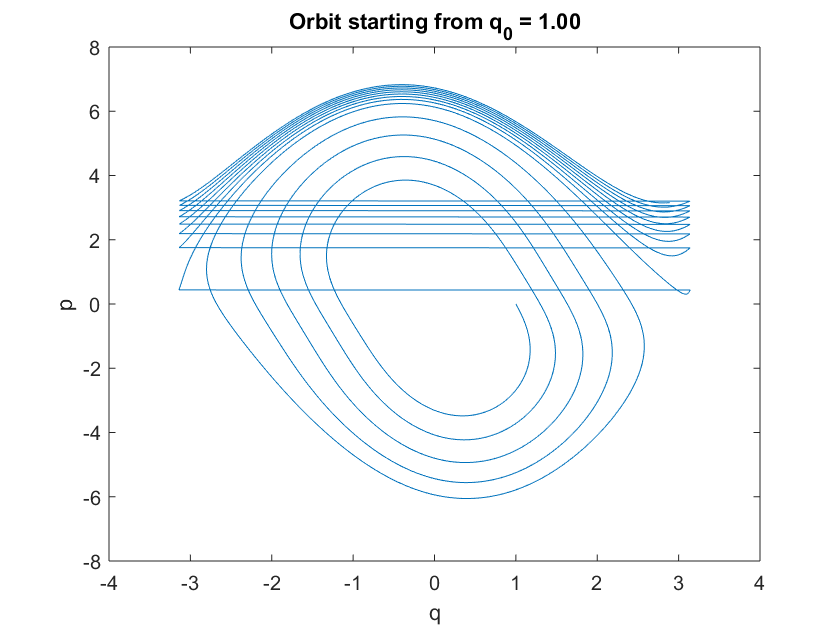

% Display the output in phase space
figure;
plot(sol.y(1,:),sol.y(2,:));
xlabel('q');
ylabel('p');
title(sprintf('Orbit starting from q_0 = %.2f',q0));